clear;
close all;

Set Parameter

img_org = "img_org.jpg";
level = [2 4 8 64 128 256];

获取图片信息

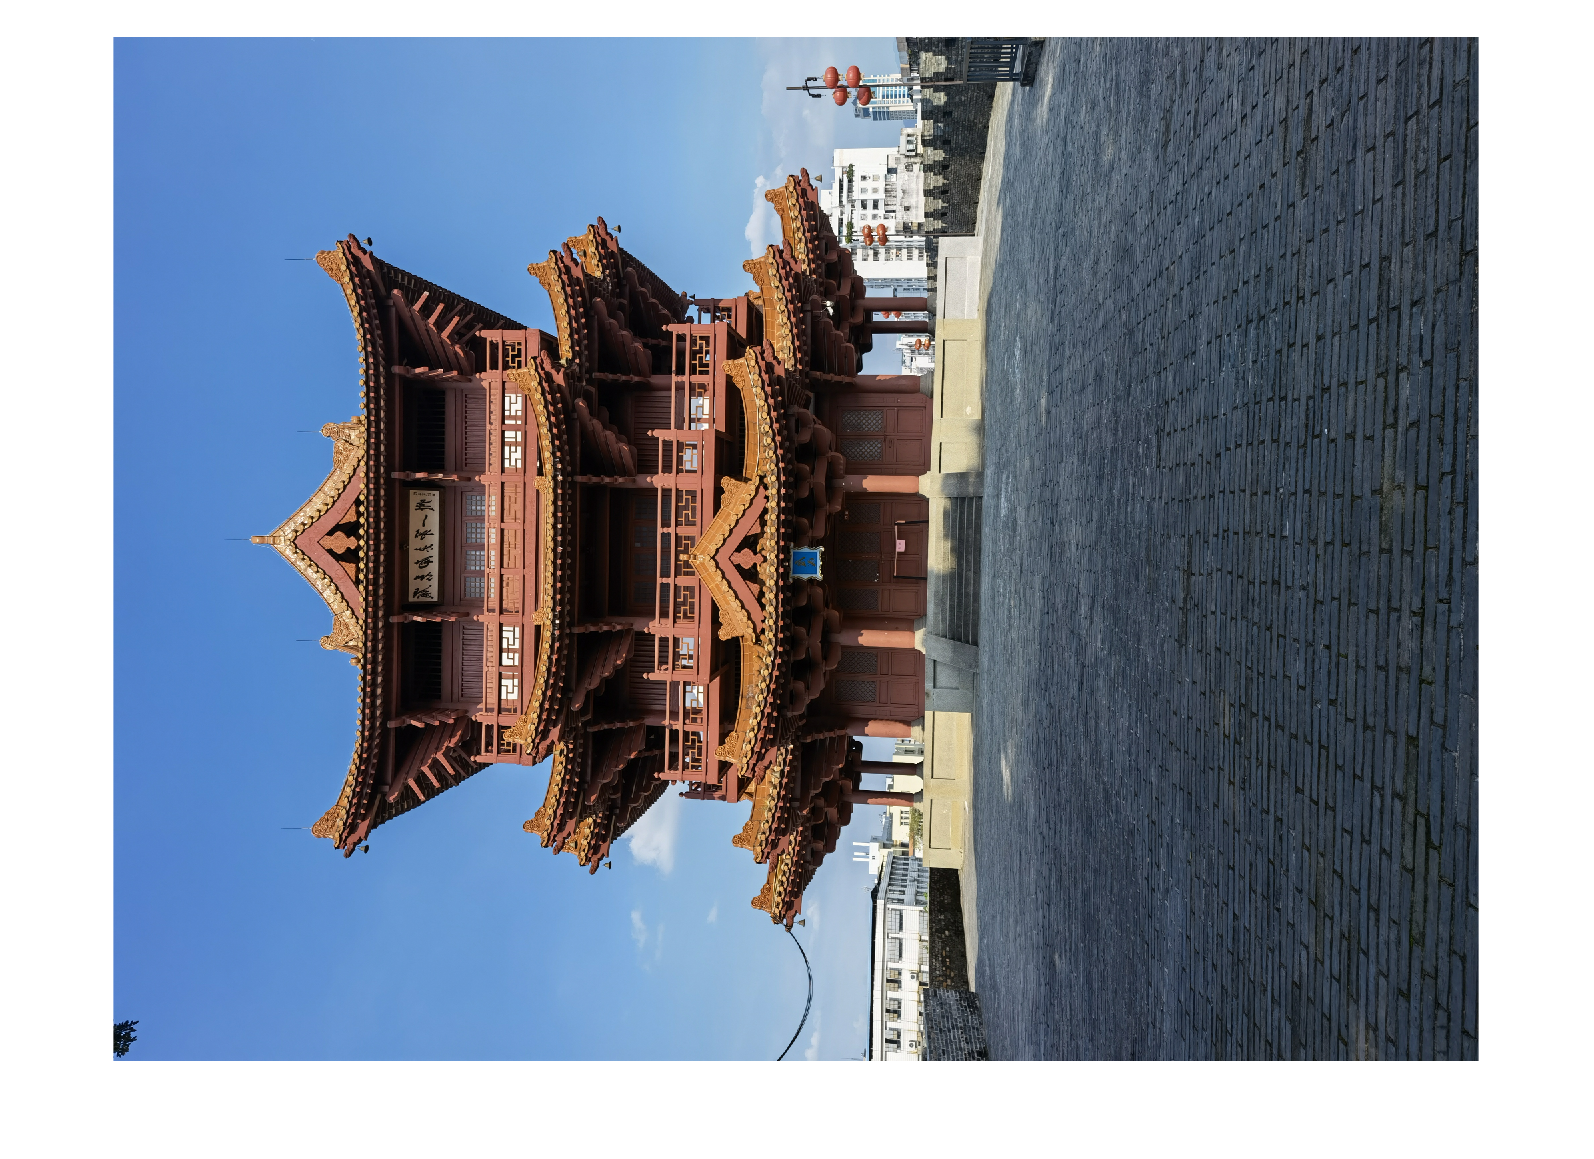

img_data = imread(img_org);
% 旋转图片
for P = 1:3
    img_org_data(:,:,P) = img_data(:,:,P)';
end
[h,w,p] = size(img_org_data);

figure(1);
imshow(img_org_data);

处理灰度级

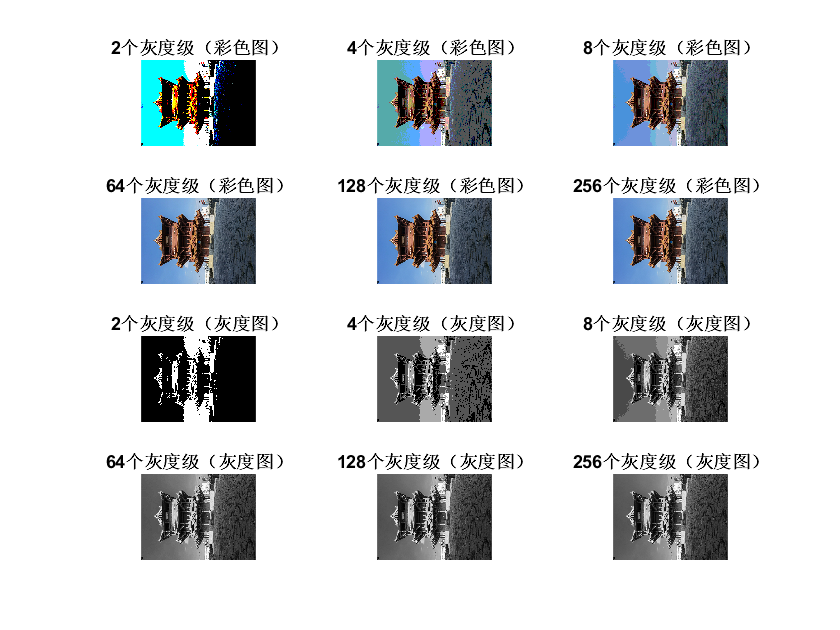

figure(2);
for j = 1:6
    L = level(j);
    d = 255 / (L - 1);
    img_color = zeros(h,w,p); 
    img_gray = zeros(h,w);

    for H = 1:h
        for W = 1:w
            for P = 1:p
                img_color(H,W,P) = round(round(img_org_data(H,W,P) / d) * d);
            end
            img_gray(H,W) = round(round(img_org_data(H,W) / d) * d);
        end
    end

    subplot(4,3,j);
    imshow(uint8(img_color));
    num_str = L + "个灰度级（彩色图）";
    t = title(num_str);
    t.FontSize = 16;
    
    subplot(4,3,6+j);
    imshow(uint8(img_gray));
    num_str = L + "个灰度级（灰度图）";
    t = title(num_str);
    t.FontSize = 16;
end

Show the picture of Y,Cb,Cr

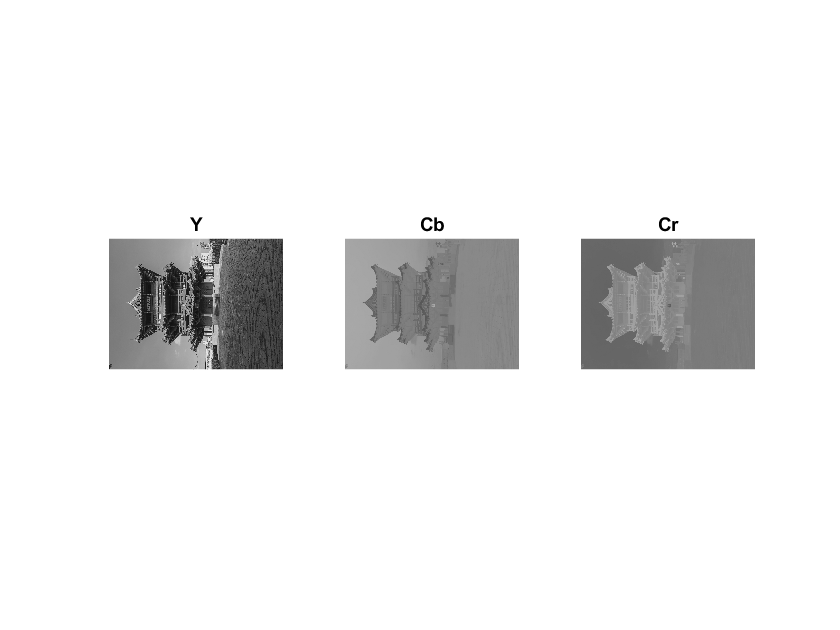

img_ycbcr = rgb2ycbcr(img_org_data);

Y = img_ycbcr(:,:,1);
Cb = img_ycbcr(:,:,2);
Cr = img_ycbcr(:,:,3);

figure(3);
subplot(1,3,1);
imshow(Y);
title("Y");

subplot(1,3,2);
imshow(Cb);
title("Cb");

subplot(1,3,3);
imshow(Cr);
title("Cr");

下采样

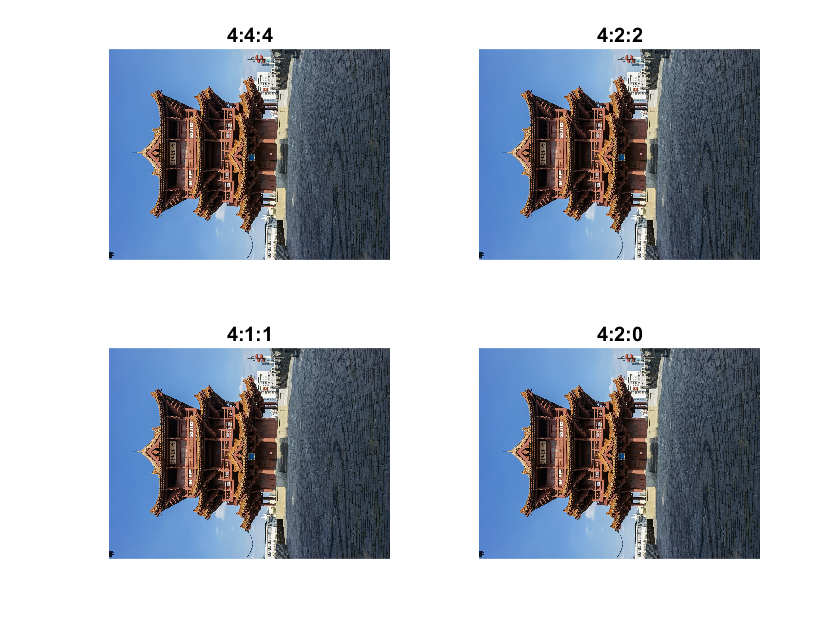

figure(4);

% 4:4:4
img_444(:,:,1) = Y;
img_444(:,:,2) = Cb;
img_444(:,:,3) = Cr;
img_444 = ycbcr2rgb(img_444);
subplot(2,2,1);
imshow(img_444);
title("4:4:4");

% 4:2:2
Cb_422 = double(zeros(h,w));
Cr_422 = double(zeros(h,w));


for H = 1:1:h
    for W = 2:2:w
        Cb_422(H,W) = Cb(H,W);
        Cb_422(H,W-1) = Cb_422(H,W);
        Cr_422(H,W) = Cr(H,W);
        Cr_422(H,W-1) = Cr_422(H,W);
    end
end

img_422(:,:,1) = Y;
img_422(:,:,2) = Cb_422;
img_422(:,:,3) = Cr_422;
img_422 = ycbcr2rgb(img_422);
subplot(2,2,2);
imshow(img_422);
title("4:2:2");

% 4:1:1
Cb_411 = double(zeros(h,w));
Cr_411 = double(zeros(h,w));

for H = 1:1:h
    for W = 4:4:w
        Cb_411(H,W) = Cb(H,W);
        Cb_411(H,W-1) = Cb_411(H,W);
        Cb_411(H,W-2) = Cb_411(H,W);
        Cb_411(H,W-3) = Cb_411(H,W);
        Cr_411(H,W) = Cr(H,W);
        Cr_411(H,W-1) = Cr_411(H,W);
        Cr_411(H,W-2) = Cr_411(H,W);
        Cr_411(H,W-3) = Cr_411(H,W);
    end
end
img_411(:,:,1) = Y;
img_411(:,:,2) = Cb_411;
img_411(:,:,3) = Cr_411;
img_411 = ycbcr2rgb(img_411);
subplot(2,2,3);
imshow(img_411);
title("4:1:1");

% 4:2:0
Cb_420 = double(zeros(h,w));
Cr_420 = double(zeros(h,w));

for H = 2:2:h
    for W = 2:2:w
        Cb_420(H,W) = Cb(H,W);
        Cb_420(H,W-1) = Cb_420(H,W);
        Cr_420(H,W) = Cr(H,W);
        Cr_420(H,W-1) = Cr_420(H,W);
    end
    Cb_420(H-1,:) = Cb_420(H,:);
    Cr_420(H-1,:) = Cr_420(H,:);
end

img_420(:,:,1) = Y;
img_420(:,:,2) = Cb_420;
img_420(:,:,3) = Cr_420;
img_420 = ycbcr2rgb(img_420);
subplot(2,2,4);
imshow(img_420);
title("4:2:0");